% house_simulate(timespan, height_aperture, width_aperture, area_floor, thickness_floor, thickness_insulation)
[T, Y, debug] = house_simulate([1, (365 * 24 * 60 * 60)], 5, 10, 5000, 0.5, 0.5, 1000)

T = 	1.0e+07 *

    0.0000
    0.0000
    0.0001
    0.0001
    0.0001
    0.0001
    0.0002
    0.0002
    0.0002
    0.0002


Y =   279.0000  279.0000
  279.0001  279.0026
  279.0013  279.0052
  279.0039  279.0078
  279.0066  279.0104
  279.0085  279.0130
  279.0106  279.0156
  279.0130  279.0181
  279.0155  279.0207
  279.0177  279.0233


debug = 	1.0e+07 *

    0.0000         0   -0.0060         0         0    0.0000
    0.0000    0.0000   -0.0060         0         0    0.0000
    0.0000    0.0000   -0.0060    0.0000         0    0.0000
    0.0001    0.0001   -0.0060   -0.0000         0    0.0000
    0.0001    0.0001   -0.0060   -0.0000         0    0.0000
    0.0001    0.0002   -0.0060   -0.0000         0    0.0000
    0.0001    0.0000   -0.0060    0.0000         0    0.0000
    0.0001    0.0000   -0.0060    0.0000         0    0.0000
    0.0001    0.0000   -0.0060    0.0000         0    0.0000
    0.0002    0.0000   -0.0060    0.0000         0    0.0000


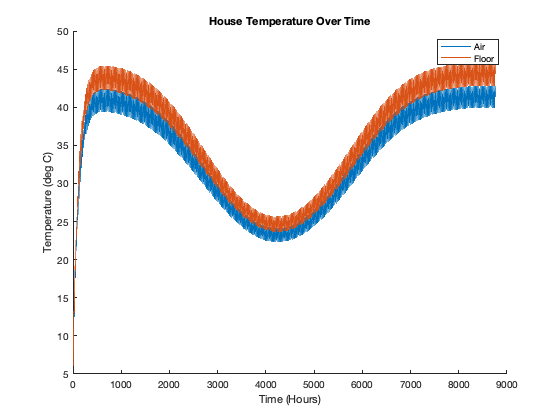

clf; hold on;

plot(T / (60 * 60), Y(:, 1) - 273);
plot(T / (60 * 60), Y(:, 2) - 273);
legend("Air", "Floor");
xlabel("Time (Hours)");
ylabel("Temperature (deg C)");
title("House Temperature Over Time");

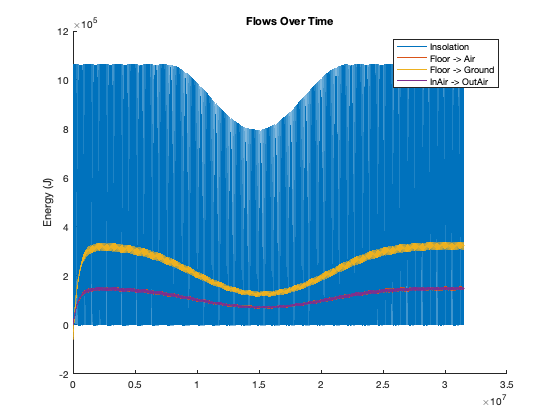

figure; clf; hold on;
%        debug(end + 1, :) = [dUdt_floor_to_air, dUdt_floor_to_ground, dUdt_air_to_air, dUdt_insolation];
plot(debug(:, 1), debug(:, 5));
plot(debug(:, 1), debug(:, 2));
plot(debug(:, 1), debug(:, 3));
plot(debug(:, 1), debug(:, 4));
ylabel("Energy (J)");

%yyaxis right;
%plot(debug(:, 1), debug(:, 6));
%ylabel("Solar Elevation (Degrees Above Horizon)");
legend("Insolation", "Floor -> Air", "Floor -> Ground", "InAir -> OutAir");
title("Flows Over Time");